# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Luke\Simon\RawData_All'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                      % Activates Parallel Computing for PP and Analysis only
Deci.GCom               = false; 
Deci.Folder.Version     = ['C:\Users\User\Desktop\Luke\Simon\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions 

Deci.DT.Type = 'Simon_Polymerase';
Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34] [23 24]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq                                                               % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.AddLocks = true; 
Deci.DT.Displace.Markers = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34]};
Deci.DT.Displace.Duration = 1;
Deci.DT.Displace.Num = -1;

Deci.DT.Block.Markers   = {40};
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

Deci.Art.AddComponents =  false;

## 4. Analysis

if Deci.Step > 3
    Deci.DT.Markers    = {[14 15] [300 400] [31 34] [1014 1015] [1300 1400] [1031 1034]};                    
end

%Locktypes = {'Simon_Cor'}
%LockTypes = {'Simon_Cor' 'Simon_Con' 'Simon_Side' 'Simon_Contra'};
%LockTypes = {'Simon_ConCor' 'Simon_ContraCor'};
%LockTypes = {'Simon_ContraCor'};
%Locktypes = {'Simon_Congruence' 'Simon_Laterality'};
%Locktypes = {'Simon_Cor' 'Simon_Congruence' 'Simon_ConCor'};
%Locktypes = {'SimonConn_Cor'};
%Locktypes = {'Simon_Congruence'}
%LockTypes = {'Simon_Conflict'}
%Locktypes = {'Simon_CongruenceDuplets' 
%Locktypes = {'Simon_CorrectnessDuplets'}
%Locktypes = {'Simon_CongruencexCorrectnessDuplets'}
Locktypes = {'Simon_CorrectCongruenceDuplets'}

Locktypes = 1×1 cell array
    {'Simon_CorrectCongruenceDuplets'}


%Locktypes = {'Simon_Congruence'}
%Locktypes = {'Simon_Congruence_StimLocked_BBcorr'}
%Locktypes = {'Simon_Correct_StimLocked_BBcorr'}

## 5. Plotting

## ** 6. Run**

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 5
        Proceed: 0
           PCom: 0
           GCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]
            ICA: [1×1 struct]
            Art: [1×1 struct]
       Analysis: [1×1 struct]
           Plot: [1×1 struct]


Running Deci for 25 subjects
 
----------------------
 
Plotting Brain-Behavior Correlation
Loading Plottor for Subject #1: Simon_EEGTest1_001PS
Loading Plottor for Subject #2: Simon_EEGTest1_002PS
Loading Plottor for Subject #3: Simon_EEGTest1_007PS
Loading Plottor for Subject #4: Simon_EEGTest1_008CG
Loading Plottor for Subject #5: Simon_EEGTest1_011PS
Loading Plottor for Subject #6: Simon_EEGTest1_015CG
Loading Plottor for Subject #7: Simon_EEGTest1_018PS
Loading Plottor for Subject #8: Simon_EEGTest1_026CG
Loading Plottor for Subject #9: Simon_EEGTest1_032CG
Loading Plottor for Subject #10: Simon_EEGTest1_046PS
Loading Plottor for Subject #11: Simon_EEGTest_002CG
Loading Plottor for Subject #12: Simon_EEGTest_004PS
Loading Plottor for Subject #13: Simon_EEGTest_007CG
Loading Plottor for Subject #14: Simon_EEGTest_009PS
Loading Plottor for Subject #15: Simon_EEGTest_010CG
Loading Plottor for Subject #16: Simon_EEGTest_011CG
Loading Plottor for Subject #17: Simon_EEGTest_013PS
Loadin

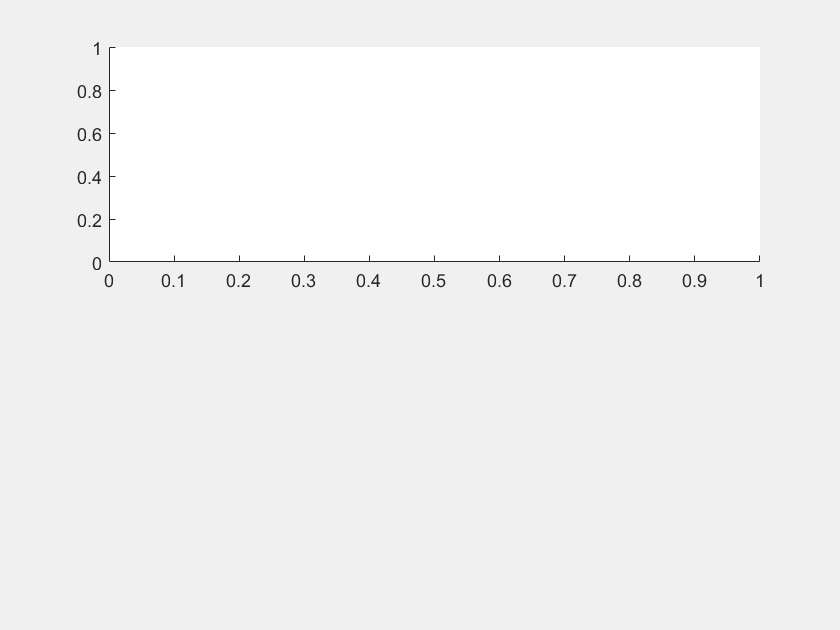

if Deci.Step == 4
    for AnalysisLocks = Locktypes
        Deci_Wavelet;
        
        Deci.Analysis.Freq.foi           = 3:1:60;                           % Frequency of Interest
        
        
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));                                                         % Width
        Deci.Analysis.Freq.Toi           = [-.5 1.5];  
        
        
        Deci.SubjectList        = 'gui';
       
        Deci.Analysis.Freq.do  = false;
        Deci.Analysis.ERP.do  = false;
        Deci.Analysis.Connectivity.do = false;
        
        eval(AnalysisLocks{1})
        Deci_Backend(Deci);
        
    end
else
    
    Simon_CorrectCongruenceDuplets;
    
    Deci.Run.Behavior = false;
    Deci.Run.Freq =false;
    Deci.Run.ERP =false;
    Deci.Run.CFC = false;
    Deci.Run.Extra = true;
    
    
    Deci.Plot.BslRef = 'Rsp Onset';
    Deci.Plot.Lock =   'Next Rsp';
    
    Deci.Plot.GrandAverage = true;
    Deci.Plot.FreqYScale = 'log';
%     Deci.Plot.ColorMap = flip(CoolMap);
    Deci.Plot.ImageType = 'contourf';
    
    
    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [-.2 0];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Square.do  =true;
    Deci.Plot.Square.Foi     = [1 inf];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [-.5 1.5];                   % Time of Interest
    Deci.Plot.Square.Channel = [{'FCz' 'Cz'}];                % Channel of Interest
    
    Deci.Plot.Wire.do    =true;
    Deci.Plot.Wire.Foi     =   [4 8];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Wire.Channel = [{'Cz' 'FCz'}];              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [4 8];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     = [0 .2];                   % Time of Interest
    Deci.Plot.Bar.Channel =  [{'FCz' 'Cz'}];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        Deci.Plot.Bsl     = [-.25 -.05];
    else
        Deci.Plot.Bsl     = [-.2 0];
    end
    
    if Deci.Run.Extra
        Deci.Plot.BslType = 'none';
    end
    %Luke(1/17/20) changed RSP reference to [-.25 -.05] & else [-.2 0] 
    
    
    if  Deci.Plot.Square.do
        Omnibus = true;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            %Deci.Plot.BslType = 'db';
            Deci.Plot.Stat.FPlots =  false;
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.correctm = 'fdr';
        end
        Deci.Plot.Stat.FPlots =  false;
    end
    
    if Deci.Plot.Topo.do 
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    end
    
    if Deci.Plot.Wire.do
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
    end
        
    
    if Deci.Plot.Bar.do
        Deci.Plot.Stat.do = false;
    end
    
     if Deci.Plot.Wire.do
        Deci.Plot.Stat.do = false;
    end
    
    Deci_Backend(Deci);
end